# Pareto

## Param

clear
close all
k=1;
b=0.25*10^(-4);


## Decision variable

x=50:50:1400

x =           50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400


v=25:25:500

v =     25    50    75   100   125   150   175   200   225   250   275   300   325   350   375   400   425   450   475   500


## Objectif fct

Profit=(15-2.*x./v').*x-b*x.*v'.^2

Profit = 	1.0e+05 *

    0.0055    0.0070    0.0045   -0.0020   -0.0125   -0.0270   -0.0456   -0.0681   -0.0946   -0.1251   -0.1596   -0.1981   -0.2406   -0.2871   -0.3376   -0.3921   -0.4506   -0.5131   -0.5796   -0.6502   -0.7247   -0.8032   -0.8857   -0.9722   -1.0627   -1.1572   -1.2557   -1.3582
    0.0065    0.0109    0.0134    0.0139    0.0123    0.0088    0.0033   -0.0043   -0.0138   -0.0253   -0.0388   -0.0544   -0.0719   -0.0914   -0.1130   -0.1365   -0.1620   -0.1896   -0.2191   -0.2506   -0.2842   -0.3197   -0.3572   -0.3967   -0.4383   -0.4818   -0.5273   -0.5749
    0.0068    0.0122    0.0163    0.0191    0.0205    0.0206    0.0193    0.0168    0.0129    0.0076    0.0011   -0.0068   -0.0161   -0.0267   -0.0386   -0.0518   -0.0664   -0.0823   -0.0995   -0.1181   -0.1380   -0.1592   -0.1818   -0.2057   -0.2309   -0.2575   -0.2854   -0.3146
    0.0069    0.0127    0.0176    0.0215    0.0244    0.0262    0.0271    0.0270    0.0259    0.0238    0.0206    0.0165    0.0114    0.

Risk=k*x.*ones(length(v),1)

Risk =           50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400
          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400
          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300       

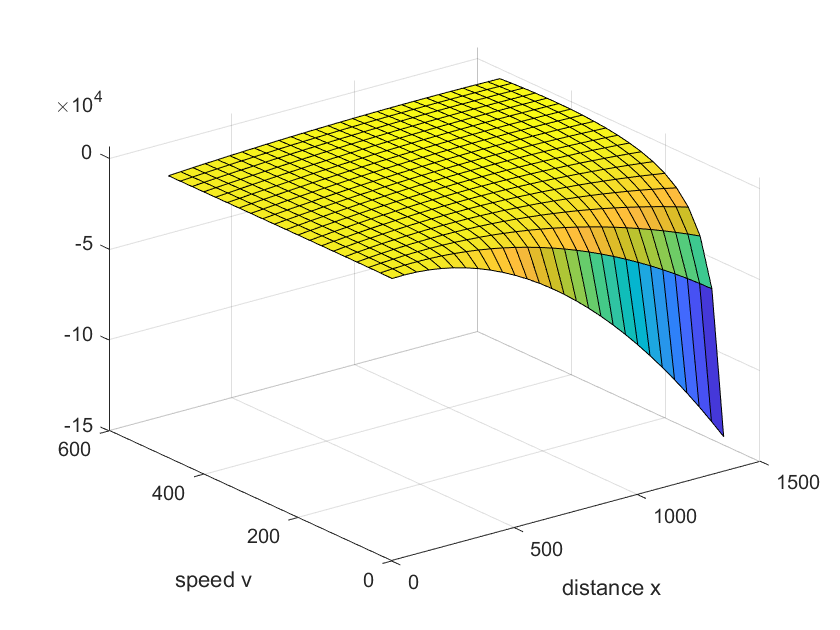

figure(1)
surf(x,v,Profit)
xlabel('distance x')
ylabel('speed v')

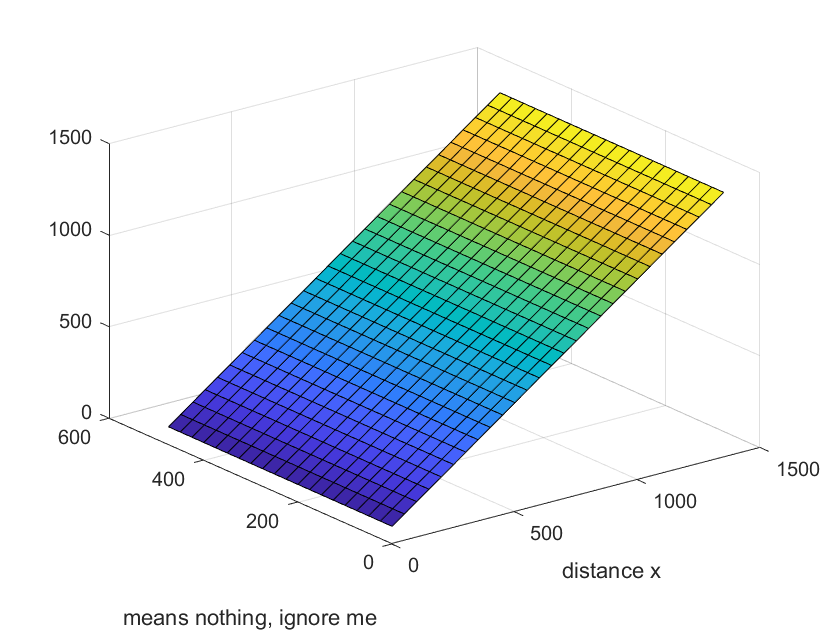

figure(2)
surf(x,v,Risk)
xlabel('distance x')
ylabel('means nothing, ignore me')

## Decision space solutions

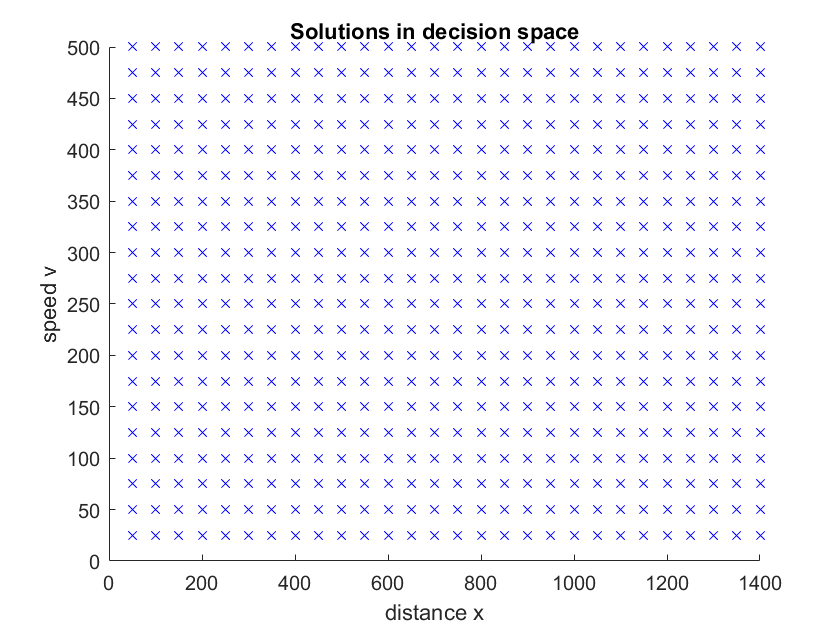

figure(3)
hold on
for i=1:length(x)
    for j=1:length(v)
        plot(x(i),v(j),'bx')
    end
end
hold off
title('Solutions in decision space')
xlabel('distance x')
ylabel('speed v')

## Objective space

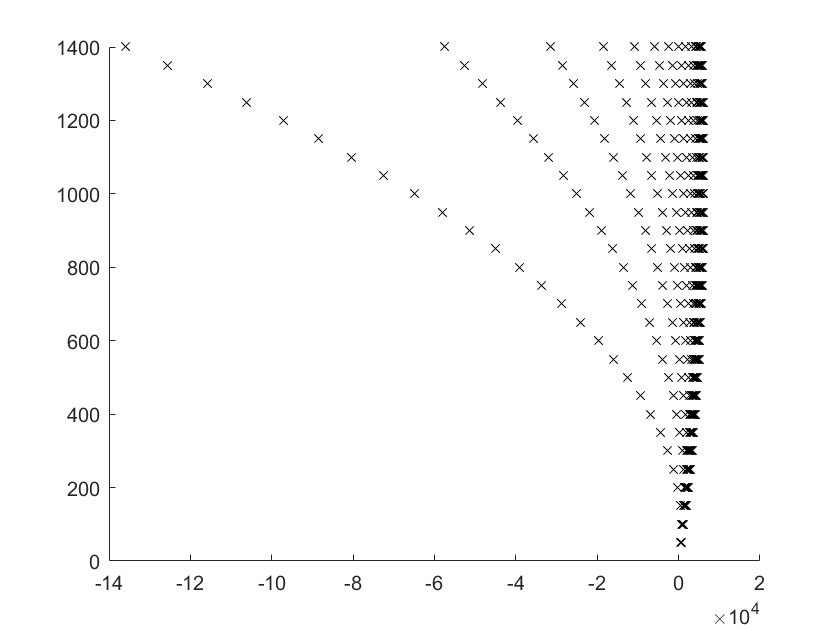

figure(4)
hold on
plot(Profit,Risk,'kx')

## Weighted sum and scale

Profitscale = (Profit-min(min(Profit)))/(max(max(Profit))-min(min(Profit)));
Riskscale = (Risk-min(min(Risk)))/(max(max(Risk))-min(min(Risk)))